% Load the ONNX model
modelfile = "C:\Users\msi\Documents\ELTE\ImageandSignal\Assignment3\LicensePlateDetection\LicensePlate5\weights\best.onnx";
net = importNetworkFromONNX(modelfile);

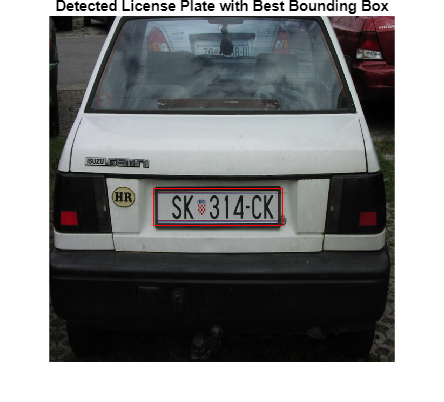


% Load and preprocess the input image
imagePath = 'P9170014.jpg'; % Replace with your image path
inputImage = imread(imagePath);
resizedImage = imresize(inputImage, [640, 640]);

% Normalize the image
inputImageNormalized = double(resizedImage) / 255; % Normalize to [0, 1]

% Prepare the image for the model
inputImageBatch = permute(inputImageNormalized, [1, 2, 3, 4]); % Convert to [Batch, Channels, Height, Width]

% Predict using the model
predictions = predict(net, inputImageBatch);

% Extract bounding boxes and confidence scores
% predictions is [1x5x8400], so we reshape it for easier handling
predictions = squeeze(predictions); % Remove singleton batch dimension, resulting in [5x8400]

% Bounding boxes (x_center, y_center, width, height)
boundingBoxes = predictions(1:4, :)'; % Transpose to get [8400x4]
% Confidence scores
confidenceScores = predictions(5, :)'; % Transpose to get [8400x1]
% Find the best bounding box based on the highest confidence score
[~, bestIdx] = max(confidenceScores);
bestBoundingBox = boundingBoxes(bestIdx, :); % [x_center, y_center, width, height]

% Convert the bounding box to [x_min, y_min, x_max, y_max] format
x_center = bestBoundingBox(1);
y_center = bestBoundingBox(2);
width = bestBoundingBox(3);
height = bestBoundingBox(4); 

x_min = x_center - width / 2;
y_min = y_center - height / 2;
x_max = x_center + width / 2;
y_max = y_center + height / 2;

% Draw the best bounding box on the original image
detectedImage = insertShape(resizedImage, 'Rectangle', [x_min, y_min, width, height], 'Color', 'red', 'LineWidth', 2);


% Display the image with the bounding box
imshow(detectedImage);
title('Detected License Plate with Best Bounding Box');